# lora sat

## sat characteristics

%lora sensitivity = -174 +10log10(B)+NF+SNR (SNR depends on SF)

%satelliteParamsSource = custom;
% Table 6.2-7: Set-4 satellite parameters for system level simulator calibration 
% (based on R1-2101019 - Thales, Sateliot, Gatehouse) (page 20)

satellite = struct;
satellite.EIRPDensity = 21.45;    % dBW/MHz 
satellite.RxGByT = -18.6;        % dB/K  *=Gr-Ts with Ts=  system noise temp
satellite.Altitude = 600e3;    % m *original 600


## UE characteristics

% power class 5: 100mW (page 16,17) PC3: NF=7,Ptx=23
ue = struct;
ue.TxPower = 20;               % dBm
ue.TxGain = 0;                 % dBi
ue.TxCableLoss = 0;            % dB
ue.RxNoiseFigure = 9;          % dB
ue.RxGain = 0;                 % dBi
ue.RxAntennaTemperature = 290; % K
ue.RxAmbientTemperature = 290; % K

## link characteristics

link = struct;
link.Direction = "downlink";    % "uplink", "downlink"
link.ElevationAngle = 10:10:90;         % degrees (Vector of elevation angles)
link.Frequency = 2e9;                     % Hz
link.Bandwidth = 180e3;                   % Hz *lora 125e3
link.ShadowMargin = 3;                    % dB
link.AdditionalLosses = 0;                % dB
link.PolarizationLoss = 3;                % dB
link.ScintillationLosses = 2.2;           % dB
link.AtmosphericLosses = 0.1;             % dB *function of elevation angle

## modulation

modulation = "BPSK"; % Modulation scheme
nBits = 208;                       % Number of useful bits (transport block size)
nSymbols = 160;                    % Number of symbols used for transmission
nRep = 1;                          % Number of repetitions
nSF = 8;                           % Number of subframes (used in downlink)
nRU = 1;                           % Number of resource units (used in uplink)

nDSC = 72;                         % Number of data subcarriers (6 resource blocks)
nFFT = 128;                        % FFT length
tsamp = 1/1.92e6;                  % Sample time (in s)
td = nFFT*tsamp;                   % Data symbol duration (in s)
nCP = 9;                           % Number of cyclic prefix samples
tCP = nCP*tsamp;                   % Cyclic prefix duration (in s)
osr = 1;                           % Oversampling factor

% Reference Eb/No in dB
if strcmpi(modulation,"16-QAM")
    % Modulation scheme is 16-QAM
    ebnoRef = 14.4;
else 
    % Modulation scheme is either BPSK or QPSK
    ebnoRef = 10.5;
end
% Modulation order
m = 1;
if strcmpi(modulation,"QPSK")
    m = 2;
elseif strcmpi(modulation,"16-QAM")
    m = 4;
end

% Number of CRC bits
nCRC = 24;

% Calculate the effective code rate and the reference CNR
if strcmpi(link.Direction,"downlink")
    Reff = (nBits + nCRC)/(nSF*nSymbols*m*nRep);
else % "uplink"
    Reff = (nBits + nCRC)/(nRU*nSymbols*m*nRep);
end
cnrRef = ebnoRef + 10*log10(m*Reff) + 10*log10(nDSC/nFFT) + ...
        10*log10(td/(td + tCP)) - 10*log10(osr);

disp("Reference CNR: " + cnrRef + " dB")

Reference CNR: 0.2889 dB


% Get the satellite parameters based on satelliteParamsSource
% if ~strcmpi(satelliteParamsSource,"custom")
%     satellite = getSatelliteParams(satelliteParamsSource);
% end

% Calculate EIRP when the satellite is a transmitter (dB)
% To get a value in decibels from density: 
% Value in dB = Value in dB/MHz + 10*log10[BW in MHz]
satellite.EIRP = satellite.EIRPDensity + 10*log10(link.Bandwidth/1e6);

% Calculate EIRP when the UE is a transmitter (dB)
% To get a value in decibels from dBm: dB = dBm - 30
ue.EIRP = (ue.TxPower-30) + ue.TxGain - ue.TxCableLoss;

% Calculate the gain-to-noise temperature or the figure of merit for the UE
% as a receiver.
ue.RxGByT = ue.RxGain - ue.RxNoiseFigure ...
    - 10*log10(ue.RxAmbientTemperature + ...
    (ue.RxAntennaTemperature-ue.RxAmbientTemperature)*10^(-0.1*ue.RxNoiseFigure));

% Set the transmitter and the receiver based on the link direction
if strcmpi(link.Direction,"uplink")
    tx = ue;
    rx = satellite;
else
    tx = satellite;
    rx = ue;
end

% Range of elevation angles
elevAngles = link.ElevationAngle(:);
numElevAngles = numel(elevAngles);

% Calculate the distance from the satellite to the ground station for all
% elevation angles
re = physconst("earthradius");
c = physconst("lightspeed");
h = satellite.Altitude;
d = -re*sind(elevAngles) + sqrt((re*sind(elevAngles)).^2 + h*h + 2*re*h);

% Get the total atmospheric losses for each elevation angle
totalAtmosphericLoss = zeros(numElevAngles,1);
totalAtmosphericLoss(:) = link.AtmosphericLosses + link.ScintillationLosses;

% Define the configuration parameters
config = satelliteCNRConfig;
config.TransmitterPower = tx.EIRP;
config.TransmitterAntennaGain = 0;
config.Frequency = link.Frequency/1e9;          % GHz
config.GainToNoiseTemperatureRatio = rx.RxGByT;
config.Bandwidth = link.Bandwidth/1e6;          % MHz

% Compute the CNR and the free space path loss for each elevation angle
cnr = zeros(numElevAngles,1);
pathLoss = cnr;
for index = 1:numElevAngles
    config.Distance = d(index)/1e3;                                         % km
    config.MiscellaneousLoss = totalAtmosphericLoss(index) + ...
         link.PolarizationLoss + link.ShadowMargin + link.AdditionalLosses;
    [cnr(index),cnrInfo] = satelliteCNR(config);
    pathLoss(index) = cnrInfo.FSPL;
end

## cnr(elevation angle)


% Report the results in a table
table(elevAngles,cnr,pathLoss,VariableNames=["Elevation Angle (degrees)", "CNR (dB)", "FSPL (dB)"])

ans = 9×3 table
    Elevation Angle (degrees)    CNR (dB)    FSPL (dB)
    _________________________    ________    _________

               10                -16.062      164.19  
               20                -13.217      161.34  
               30                -10.972       159.1  
               40                -9.2559      157.38  
               50                -7.9689      156.09  
               60                -7.0335      155.16  
               70                -6.3974      154.52  
               80                -6.0276      154.15  
               90                -5.9062      154.03  


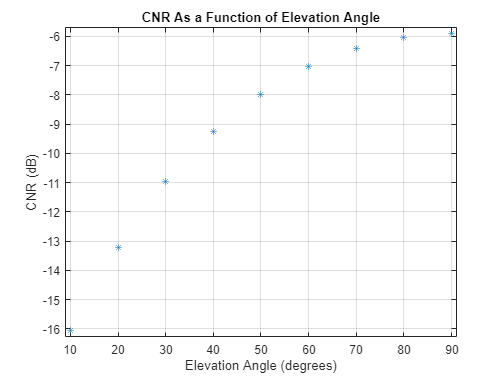


% Plot CNR as a function of the elevation angle
plot(elevAngles,cnr,"*")
title("CNR As a Function of Elevation Angle")
xlabel("Elevation Angle (degrees)")
ylabel("CNR (dB)")
ylim([min(cnr)-0.2 max(cnr)+0.2])
xlim([min(elevAngles)-1 max(elevAngles)+1])
grid on

## link margin

% Compute link margin
linkMargin = cnr - cnrRef;
% Minimum number of additional repetitions required for link closure
minRepetitions = 10.^(-linkMargin./10);
idx = linkMargin >= 0;
additionalRepetitions = minRepetitions;
additionalRepetitions(idx) = 0;
% When the link margin is negative, improve the CNR by adding repetitions.
% Calculate the required number of additional repetitions.
additionalRepetitions(~idx) = ceil(nRep*(additionalRepetitions(~idx)-1));

% Report the results in a table with this format.
% Elevation Angle | Link Margin | Min. Additional Repetitions Required
% table(elevAngles,linkMargin,additionalRepetitions, ...
%     VariableNames=["Elevation Angle (degrees)", ...
%     "Link Margin (dB)", "NRep_Add"])
table(elevAngles,linkMargin, ...
    VariableNames=["Elevation Angle (degrees)", ...
    "Link Margin (dB)"])

ans = 9×2 table
    Elevation Angle (degrees)    Link Margin (dB)
    _________________________    ________________

               10                    -16.351     
               20                    -13.506     
               30                    -11.261     
               40                    -9.5448     
               50                    -8.2578     
               60                    -7.3224     
               70                    -6.6863     
               80                    -6.3165     
               90                    -6.1951     
